# Actividad 8.1_1

### Diego Garcia Rueda

#### **Obtener **la matriz de  transformación **homogénea  T  **de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base).

Primero se realizan los comandos de limpieza de pantalla y de workspace.

clear all
close all
clc

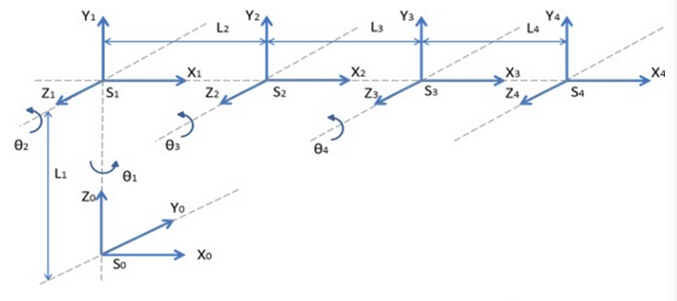

Se calculan las matrices de transformación Homogénea del modelo, en este caso las 4 longitudes (l1, l2, l3 y l4) tienen un valor de 2, este valor es completamente arbitrario:

m1_H0 = SE3;
m1_H1 = SE3(rotx(pi/2), [0,0,2]);
m1_H2 = SE3(roty(0), [2,0,0]);
m1_H3 = SE3(roty(0), [2,0,0]);
m1_H4 = SE3(roty(0), [2,0,0]);

Se realizan las matrices de transformación globales.

m1_H20 = m1_H1 * m1_H2;
m1_H30 = m1_H20 * m1_H3;
m1_H40 = m1_H30 * m1_H4;

Se establecen valores para los 3 ejes, estas seran las coordenadas con las traslaciones y las rotaciones de todas las transformaciones:

plot3(0, 0, 0); axis([-6 6 -6 6 -6 6]); grid on;
hold on;

Se establece la trama absoluta o global y posteriormente se realizan las animaciones para cada una de las tramas:

trplot(m1_H0,'rgb','axis', [-6 6 -6 6 -6 6])

%Primera trama
pause;
tranimate(m1_H0, m1_H1,'rgb','axis', [-6 6 -6 6 -6 6])
%Segunda trama
pause;
tranimate(m1_H1, m1_H20,'rgb','axis', [-6 6 -6 6 -6 6])
%Tercera trama
pause;
tranimate(m1_H20, m1_H30,'rgb','axis', [-6 6 -6 6 -6 6])
%Cuarta trama
pause;
tranimate(m1_H30, m1_H40,'rgb','axis', [-6 6 -6 6 -6 6])


disp(m1_H40)

    1         0         0         6
    0         0        -1         0
    0         1         0         2
    0         0         0         1
